# The Short Time Fourier Transform and its inverse

## Calculate and plot the STFT of a real signal

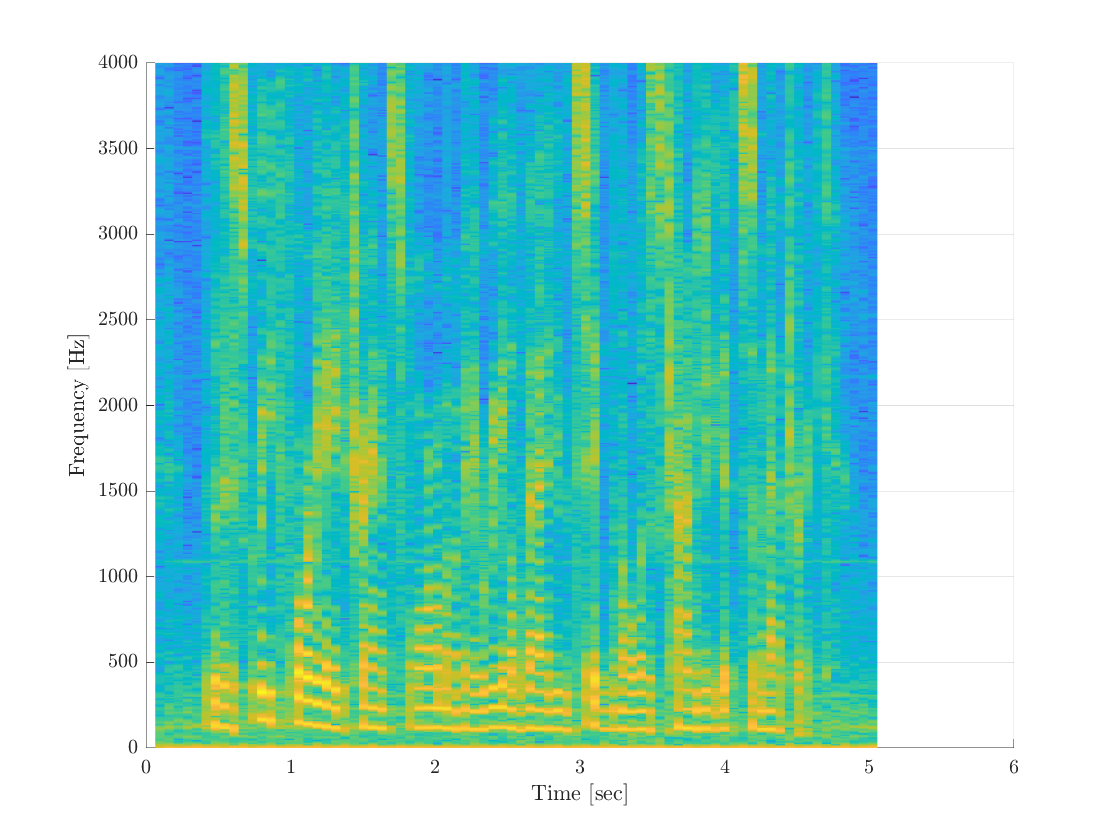

[x, fs] = audioread("SpeechDFT-16-8-mono-5secs.wav"); % read signal from file
window = hann(1024, "periodic");
hop = 512;
[S, f, t] = stft(x, window, hop, [], fs); % use [] for default values
surf(t, f(1:end/2+1), 20*log10(abs(S(1:end/2+1,:))));
view(2);
shading flat;
xlabel('Time [sec]');
ylabel('Frequency [Hz]');

## Perfect reconstruction

Verify perfect recounstruction even for windows that do not satisfy COLA

window = rand(1024,1); % generate a random window
[S, f, t] = stft(x, window, hop, [], fs); % use [] for default values
x_istft = istft(S, window, hop, 'symmetric'); % we use 'symmetric' since we can assume x is real
max(abs(x_istft(1:length(x))-x)) % calculate maximum error

ans =     13.4337e-015


## Computation time

Compare the run time of `stft` to MATLAB's builtin `spectrogram on a multichannel signal`

m = 5; % number of channels
x = [x randn(size(x,1), m-1)]; % add channels
tic; S = stft(x, window, hop); toc; 

Elapsed time is 0.019059 seconds.


tic;
for i=1:m
    S = spectrogram(x(:,i), window, length(window)-hop)
end
toc;

Elapsed time is 0.043144 seconds.


## Optimal ISTFT in the least-squares sense

Since STFT is a linear operator, there exist some matrix $A$ such that$\text{vec}(\text{STFT}(x)) = A x$ (for fixed length $x$). We begin by finding such $A$ by applying the STFT on the standard basis vectors:

N = 100; % the length of the signal
window = rand(10,1); % random window
hop = 3;
NFFT = 16;
A = reshape(stft(eye(N), window, hop, NFFT), [], N);

Verify that $A$ indeed calculates the STFT on a random signal:

x = randn(N,1);
S1 = stft(x, window, hop, NFFT);
S2 = reshape(A*x, NFFT, []);
max(abs(S1-S2), [], 'all')

ans =    993.0137e-018


Note that `A` is a tall matrix, so the STFT is not surjective. This means that for a given a 2D array $S$ there might not exist a signal $x$ whos STFT is $S$. In such cases, we can look for $x$ whos STFT is as close possible to $S$ in the least sqaures sense. This $x$ is given by $A^\dagger \text{vec}(S)$ where $A^\dagger$ is pseudo-inverse of $A$.

S = randn(size(S1))+1i*randn(size(S1)); % generate a random 2D array
x1 = pinv(A)*S(:); % ISTFT using the pseudo-inverse

Since$A$ is often a very large matrix, this method of inverting the STFT is not very practicle. Luckily, It turns out that the least-sqaures solution can be obtained without explicitly calculating $A^\dagger$.

x2 = istft(S, window, hop); % ISTFT without using the pseudo-inverse
max(abs(x2(1:length(x1))-x1)) % verify that both signals are the same

ans =      3.9860e-015


## Example: denoising of a speech signal using a binary mask

The following is an example of a very basic algorithm to denoise a speech signal using the STFT.

[x_clean,fs] = audioread("SpeechDFT-16-8-mono-5secs.wav"); % load speach file
x_clean = x_clean/std(x_clean); % normalize
soundsc(x_clean,fs);

Add washing machine noise:

noise = audioread("WashingMachine-16-8-mono-1000secs.wav");
noise = noise(1:length(x_clean));
noise = noise/std(noise); % normalize
x_noisy = x_clean + noise/2; % 6dB SNR
soundsc(x_noisy, fs);

Calculate the STFT of the noisy signal. Identify bins that contain 95% of the energy.

window = sqrt(hann(256,"periodic"));
hop = length(window)/4;
S = stft(x_noisy, window, hop);
Sabssq = abs(S).^2;
p = sort(Sabssq(:), 'descend');
thresh = p( find( cumsum(p)>=0.95*sum(p), 1 ) );
mask = Sabssq >= thresh;

Apply the binary mask on `S` and calculate the ISTFT:

S_denoised = S.*mask;
[x_denoised, k] = istft(S_denoised, window, hop, 'symmetric');
soundsc(x_denoised, fs)